# **Face Detection in an Image Using MATLAB**

## **Table of Contents:**

- Import the Image

- Convert to Grayscale

- Detect Faces

- Annotate Faces

- Display the Result

**Step-1: Import the Image**

This step loads the input image using the `imread` command

% Read the input image
img = imread('VK and MSD.png');

**Step-2: Create Face Detector**

Creates a face detector object using MATLAB’s built-in `vision.CascadeObjectDetector`.

% Create a face detector object
faceDetector = vision.CascadeObjectDetector();

**Step-3: Detect Faces**

Detects faces in the image using the detector.

% Detect faces
bboxes = step(faceDetector, img);

**Step-4: Annotate Faces**

Draws bounding boxes around detected faces.

% Annotate the detected faces
detectedImg = insertObjectAnnotation(img, 'rectangle', bboxes, 'Face');

**Step-5: Display the Result**

Displays the original image with detected faces highlighted.

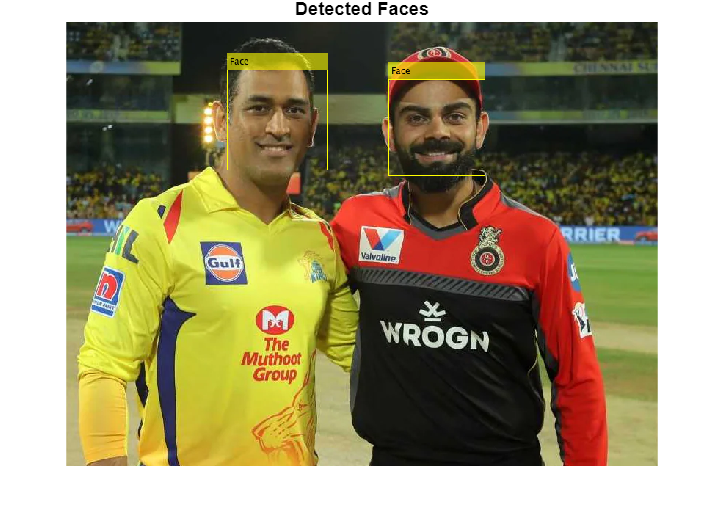

% Show the result
imshow(detectedImg);
title('Detected Faces');